## **Adding skewness**

% load checkerboard images
clear imageData
folder = 'images';
imageData = load_data(folder);
% compute camera intrinsic and extrinsic parameters for each image
clear data
data = estimating_extrinsics(imageData); 
n = length(data); % number of images

old_data = data;

data = estimating_extrinsics(data);

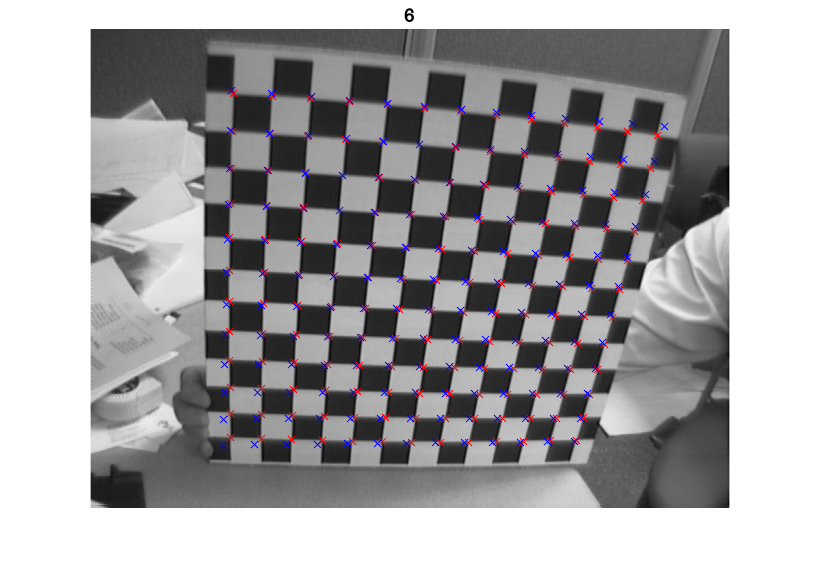

idx = 6; % choose first image
XYpixel = data(idx).XYpixel;
XYmm = data(idx).XYmm;

error = 0;

figure
imshow(data(idx).I, 'initialmagnification',200);
title(num2str(idx))
hold on

for i=1:length(XYpixel)

    % coordinates of point in mm
    Xpixel=XYpixel(i,1); % u
    Ypixel=XYpixel(i,2); % v
    Xmm=XYmm(i,1);  % x
    Ymm=XYmm(i,2); % y

    m = [Xmm; Ymm; 0; 1];
            
    P = data(idx).P;

    estimated_u =  (P(1,:)*m)/(P(3,:)*m);
    estimated_v = (P(2,:)*m)/(P(3,:)*m);
    eu = estimated_u - Xpixel; % error on u
    ev = estimated_v - Ypixel; % error on v

    error = error + eu^2 + ev^2;

    scatter(Xpixel,Ypixel, 'x', 'r');
    scatter(estimated_u,estimated_v, 'x', 'b');
end

% computed expected projection (in pixel) for each point
npoints = length(data(1).XYpixel); % number of points detected on checkerboard

for i=1:n
    XYmm = data(i).XYmm;
    for j=1:npoints
        Xmm=XYmm(j,1);  % x
        Ymm=XYmm(j,2); % y
        m = [Xmm; Ymm; 0; 1];
            
        res = data(i).P*m;
        data(i).expected(j,:) = res./res(3);
    end
end


Use these points to construct a system given by the following equations:


$$\hat{u} - u = (u-u_0) r_d^2 k_1 + (u - u_0) r_d^4 k_2$$



$$\hat{v} - v = (v-v_0) r_d^2 k_1 + (v - v_0) r_d^4 k_2$$


same for v, where $(\hat{u}, \hat{v})$  is the expected projected point, while $(u,v)$ is the one that would be obtained through undistorted projection.

% for each image (u0, v0) are the coordinates in pixel of first point
A = zeros(2*nselected, 2); % matrix A has two equations for each point of each matrix
b = zeros(2*nselected, 1);
K = data(1).K; % matrix K of intrinsic parameters
alpha_u = K(1,1);

theta = acot(K(2,2)/alpha_u)*57.2958; % skew angle between u and v axes, the angle is measured in radians
alpha_v = K(2,2);%/sin(theta);


for i=1:n
    for j=1:length(data(i).XYpixel)
        %selected = data(i).selected(j);

        u = data(i).XYpixel(j,1);
        u0 = data(i).XYpixel(1,1);
        uhat = data(i).expected(j,1);

        v = data(i).XYpixel(j,2);
        v0 = data(i).XYpixel(1,2);
        vhat = data(i).expected(j,2);

        rd = ((u-u0)/alpha_u)^2 + ((v-v0)/alpha_v)^2;
        
        %idx = (i-1)*2*10+j*2-1;
        idx = j*2 - 1;
        A(idx,1) = (u - u0)*rd^2;
        A(idx,2) = (u - u0)*rd^4;
        A(idx+1, 1) = (v - v0)*rd^2;
        A(idx + 1, 2) = (v - v0)*rd^4;
        b(idx) = uhat - u;
        b(idx+1) = vhat - v;
    end
    k = lsqr(A,b); % same as: inv((A'*A))*A'*b
    data(i).k1 = k(1);
    data(i).k2 = k(2);
end

lsqr converged at iteration 2 to a solution with relative residual 0.73.
lsqr converged at iteration 2 to a solution with relative residual 0.7.
lsqr converged at iteration 2 to a solution with relative residual 0.96.
lsqr converged at iteration 2 to a solution with relative residual 0.98.
lsqr converged at iteration 2 to a solution with relative residual 0.95.
lsqr converged at iteration 2 to a solution with relative residual 0.96.
lsqr converged at iteration 2 to a solution with relative residual 0.88.
lsqr converged at iteration 2 to a solution with relative residual 0.67.
lsqr converged at iteration 2 to a solution with relative residual 0.79.
lsqr converged at iteration 2 to a solution with relative residual 0.82.
lsqr converged at iteration 2 to a solution with relative residual 0.99.
lsqr converged at iteration 2 to a solution with relative residual 0.68.
lsqr converged at iteration 2 to a solution with relative residual 0.84.
lsqr converged at iteration 2 to a solution with rel

We have that $\hat{x} = x(1 + k_1(x^2+y^2) +k_2(x^4+2x^2y^2+y^4)$ and we want to find $x$

% new system in which the unknowns are x,y
for i=1:n
    for j=1:length(data(i).XYpixel)

        % find the new x,y for each of selected points using newotn method
        u0 = data(i).XYpixel(1,1);
        v0 = data(i).XYpixel(1,2);
        xhat = (data(i).XYpixel(j,1) - u0)/alpha_u; %data(i).XYmm(idx,1);
        yhat = (data(i).XYpixel(j,2) - v0)/alpha_v; %data(i).XYmm(idx,2);
        %fprintf("%d %d\n", xhat,yhat);
        
        k1 = data(i).k1; k2 = data(i).k2;

        f1 = @(x,y) x*(1 + k1*(x^2 + y^2) + k2*(x^4 +2*x^2*y^2 + y^4)) - xhat;
        f2 = @(x,y) y*(1 + k1*(x^2 + y^2) + k2*(x^4 +2*x^2*y^2 + y^4)) - yhat;
        J = @(x,y) [1+ 3*k1*x^2 + k1*y^2 + 5*k2*x^4 + 6*k2*x^2*y^2 + k2*y^4, ...
                    2*k1*x*y + 4*k2*x^3*y + 4*k2*x*y^3; ...
                    2*k1*x*y + 4*k2*x*y^3 + 4*k2*x^3*y, ...
                    1+ 3*k1*y^2 + k1*x^2 + 5*k2*y^4 + 6*k2*x^2*y^2 + k2*x^4];
        
        x0 = [0; 0]; % starting point for newton's method
        res = newtonMethod(f1,f2, J, x0, 10^(-8), 100);
        
        x = res(1); y = res(2);
        % update m' (pixel values of each point) using the obtained result
        % (values of x,y)
        data(i).XYpixel(j,1) = alpha_u*x + u0; %update u
        data(i).XYpixel(j,2) = alpha_v*y + v0; %update v
        %fprintf("%d %d\n", x,y);
    end
end

data = estimating_extrinsics(data); 

I = data(1).I;
J = I;

u0 = data(1).XYpixel(1,1);
v0 = data(1).XYpixel(1,2);


        rd = ((u-u0)/alpha_u)^2 + ((v-v0)/alpha_v)^2;
        u = (uhat - u0)/(1+k1rd^2 +k2rd^4) + u0;

Unrecognized function or variable 'k1rd'.

        v = (vhat - v0)/(1+k1rd^2 +k2rd^4) + v0;
        J(u,v) = I(uhat,vhat);

figure; imshowpair(I,J1,'montage');
title('Original Image (left) vs. Corrected Image (right)');

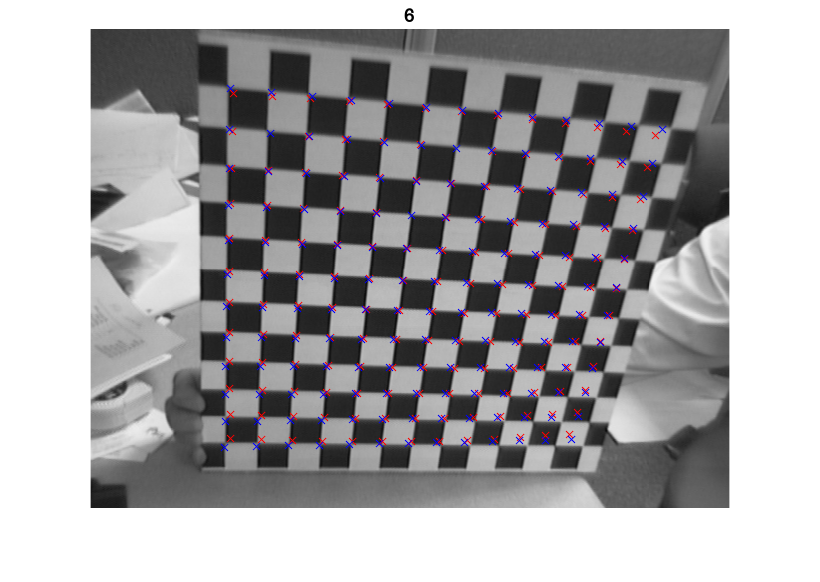

idx = 6; % choose first image
XYpixel = data(idx).XYpixel;
XYmm = data(idx).XYmm;

error = 0;


figure
imshow(J1, 'initialmagnification',200);
title(num2str(idx))
hold on

for i=1:length(XYpixel)

    % coordinates of point in mm
    Xpixel=XYpixel(i,1); % u
    Ypixel=XYpixel(i,2); % v
    Xmm=XYmm(i,1);  % x
    Ymm=XYmm(i,2); % y

    m = [Xmm; Ymm; 0; 1];
            
    P = data(idx).P;

    estimated_u =  (P(1,:)*m)/(P(3,:)*m);
    estimated_v = (P(2,:)*m)/(P(3,:)*m);
    eu = estimated_u - Xpixel; % error on u
    ev = estimated_v - Ypixel; % error on v

    error = error + eu^2 + ev^2;

    scatter(Xpixel,Ypixel, 'x', 'r');
    scatter(estimated_u,estimated_v, 'x', 'b');
end

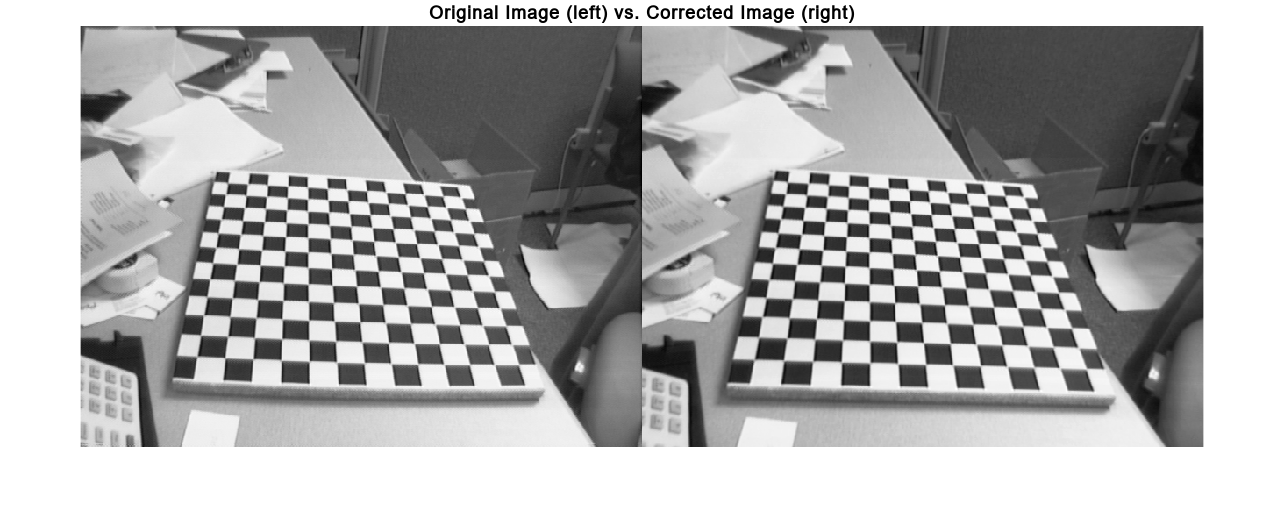

images = imageDatastore(fullfile('images'), "FileExtensions",[".jpg",".tif"]);
[imagePoints,boardSize] = detectCheckerboardPoints(images.Files,'PartialDetections', false);

squareSize = 30;
worldPoints = generateCheckerboardPoints(boardSize,squareSize);

idx = 1;
I = readimage(images,idx); 
imageSize = [size(I,1),size(I,2)];
cameraParams = estimateCameraParameters(imagePoints,worldPoints, ...
                                  'ImageSize',imageSize);

I = images.readimage(idx);
J1 = undistortImage(I,cameraParams);
figure; imshowpair(I,J1,'montage');
title('Original Image (left) vs. Corrected Image (right)');